## LAB 3 Trajectory Control

### First task

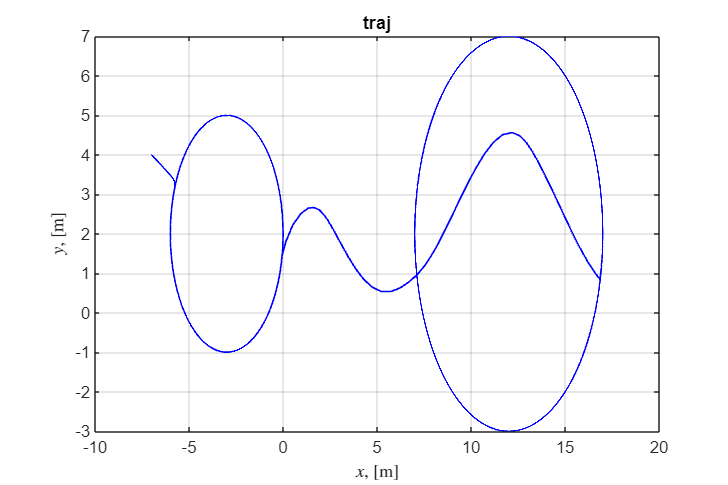

% Given
x0 = -7;
y0 = 4;
alpha0 = 3*pi/4;
m = 2.8; % in kg

% for traj
R1 = 3;
xc1 = -3;
yc1 = 2;
R3 = 5;
xc3 = 12;
yc3 = 2;

kq=3;
ke=3;

% if vs_switcher==1
% elseif vs_switcher==2
% elseif vs_switcher==3
% end

vs_switcher = 1;

vs_des = 2.5;
s_sw = [100 113.5];
Tdes=s_sw(2)+200;
warning('off');
mdlName = "first_task.slx";
sim_control = sim(mdlName,'SrcWorkspace','current');
t = sim_control.tout;
x = sim_control.simout(:,1);
y = sim_control.simout(:,2);
e = sim_control.simout(:,3);
figure('Position',[0 0 1500 1000],'units','normalized'); 
plot(x, y, ...
    'linewidth', 1,'Color','b'); grid on; hold on
xlabel('$x$, [m]','Interpreter','latex');
ylabel('$y$, [m]','Interpreter','latex');
title("traj")

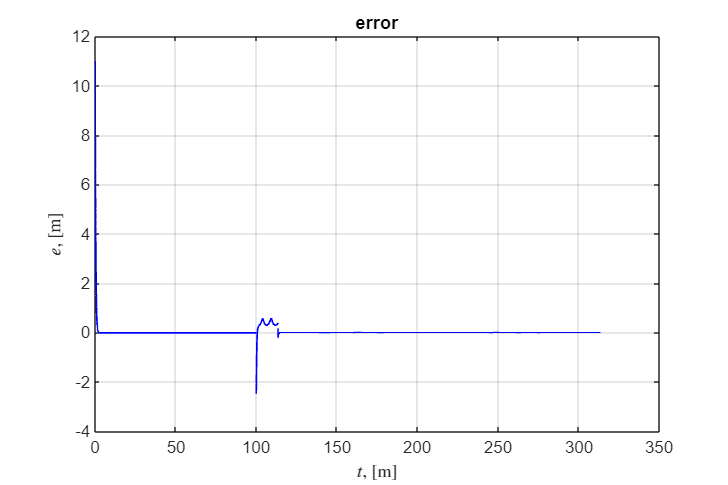

figure('Position',[0 0 1500 1000],'units','normalized'); 
plot(t, e, ...
    'linewidth', 1,'Color','b'); grid on; hold on
title("error")
% ylim([-0.1,0.1])
xlabel('$t$, [m]','Interpreter','latex');
ylabel('$e$, [m]','Interpreter','latex');

### Second task

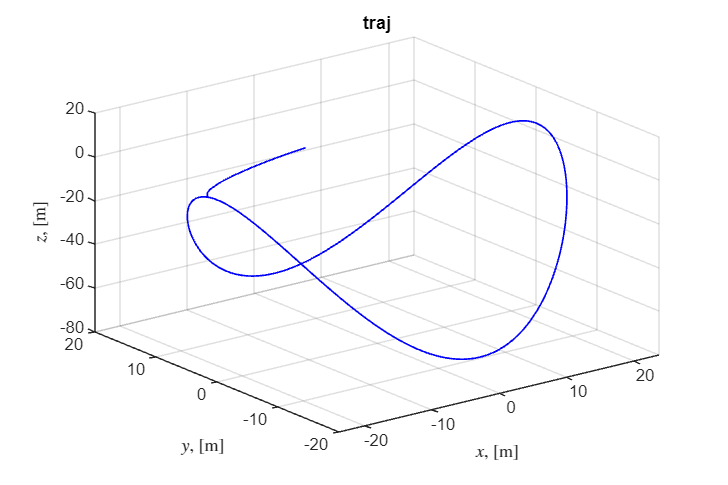

% Given
m=2.8;
j=3;
x0=-7;
y0=4;
z0=10;
q0=[x0;y0;z0];
n=[1 1 0];
nd=[1/sqrt(3) 1/sqrt(3) 1/sqrt(3)];
vs_des = 2.5;
ks=1;
k1e1=15;
k2e1=4;
k1e2=7;
k2e2=10;
kr=2;
kw=5;
Tdes=200;
warning('off');
mdlName = "second_task.slx";
sim_control = sim(mdlName,'SrcWorkspace','current');
t = sim_control.tout;
x = squeeze(sim_control.simout(1,1,:));
y = squeeze(sim_control.simout(1,2,:));
z = squeeze(sim_control.simout(1,3,:));
e1 = squeeze(sim_control.simout(1,4,:));
e2 = squeeze(sim_control.simout(1,5,:));
e_vs = squeeze(sim_control.simout(1,6,:));
n_x= squeeze(sim_control.simout(1,7,:));
n_y= squeeze(sim_control.simout(1,8,:));
n_z= squeeze(sim_control.simout(1,9,:));
e_ang_x= squeeze(sim_control.simout(1,10,:));
e_ang_y= squeeze(sim_control.simout(1,11,:));
e_ang_z= squeeze(sim_control.simout(1,12,:));
figure('Position',[0 0 1500 1000],'units','normalized'); 
plot3(x, y, z, ...
    'linewidth', 1,'Color','b'); grid on; hold on
xlabel('$x$, [m]','Interpreter','latex');
ylabel('$y$, [m]','Interpreter','latex');
zlabel('$z$, [m]','Interpreter','latex');
title("traj")

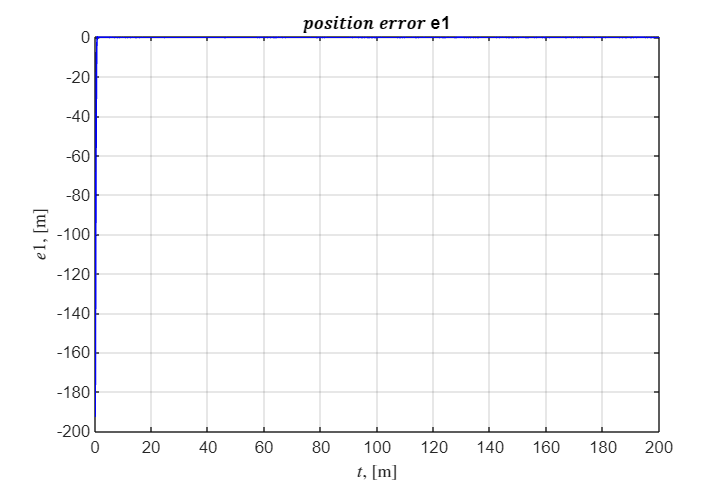

figure('Position',[0 0 1500 1000],'units','normalized'); 
plot(t, e1, ...
    'linewidth', 1,'Color','b'); grid on; hold on
xlabel('$t$, [m]','Interpreter','latex');
ylabel('$e1$, [m]','Interpreter','latex');
title("𝑝𝑜𝑠𝑖𝑡𝑖𝑜𝑛 𝑒𝑟𝑟𝑜𝑟 e1")

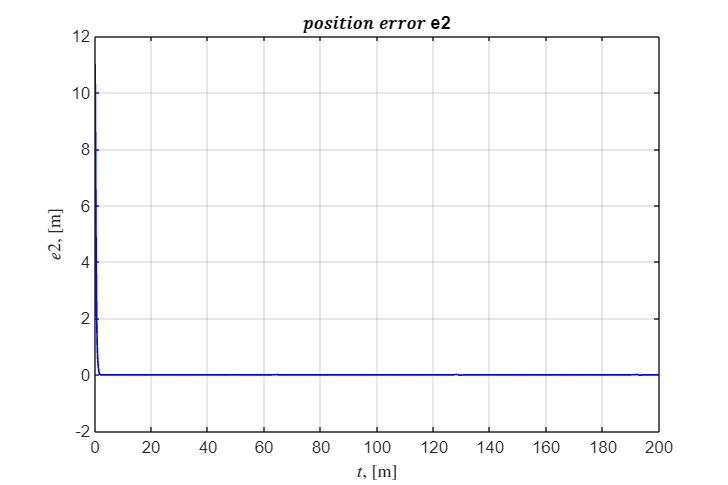

figure('Position',[0 0 1500 1000],'units','normalized'); 
plot(t, e2, ...
    'linewidth', 1,'Color','b'); grid on; hold on
xlabel('$t$, [m]','Interpreter','latex');
ylabel('$e2$, [m]','Interpreter','latex');
title("𝑝𝑜𝑠𝑖𝑡𝑖𝑜𝑛 𝑒𝑟𝑟𝑜𝑟 e2")

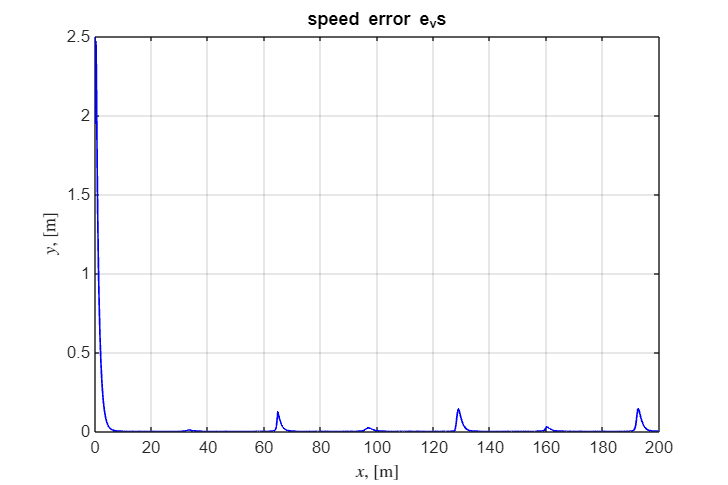

figure('Position',[0 0 1500 1000],'units','normalized'); 
plot(t, e_vs, ...
    'linewidth', 1,'Color','b'); grid on; hold on
xlabel('$x$, [m]','Interpreter','latex');
ylabel('$y$, [m]','Interpreter','latex');
title("speed error e_vs")

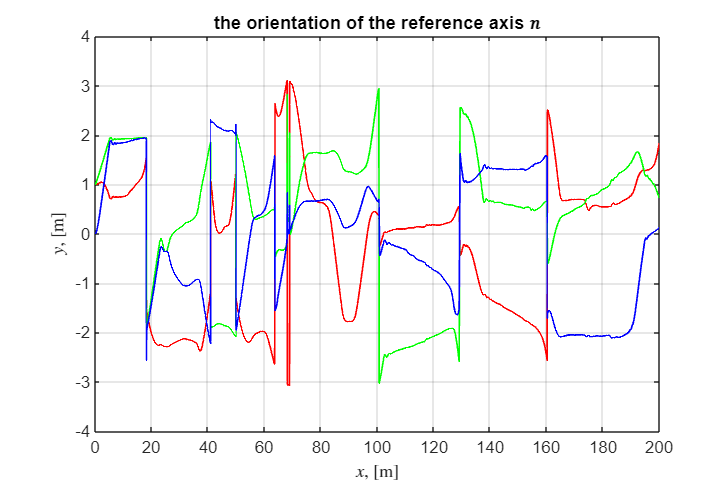

figure('Position',[0 0 1500 1000],'units','normalized'); 
plot(t, n_x, ...
    'linewidth', 1,'Color','r'); grid on; hold on
plot(t, n_y, ...
    'linewidth', 1,'Color','g');
plot(t, n_z, ...
    'linewidth', 1,'Color','b');
xlabel('$x$, [m]','Interpreter','latex');
ylabel('$y$, [m]','Interpreter','latex');
title("the orientation of the reference axis 𝑛")

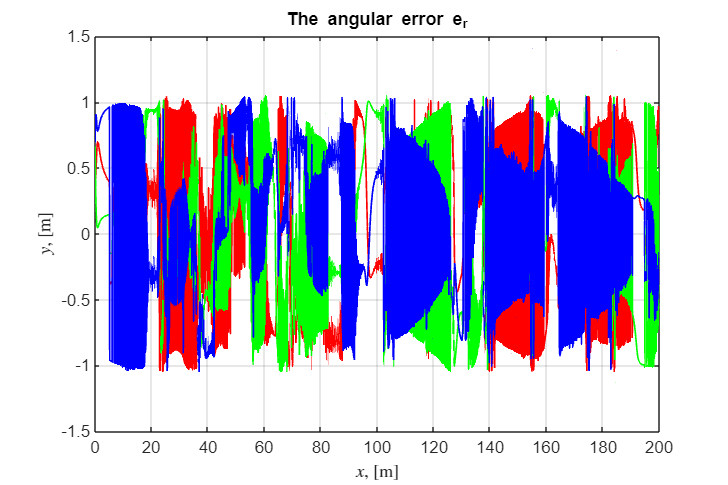

figure('Position',[0 0 1500 1000],'units','normalized'); 
plot(t, e_ang_x, ...
    'linewidth', 1,'Color','r'); grid on; hold on
plot(t, e_ang_y, ...
    'linewidth', 1,'Color','g');
plot(t, e_ang_z, ...
    'linewidth', 1,'Color','b');
xlabel('$x$, [m]','Interpreter','latex');
ylabel('$y$, [m]','Interpreter','latex');
title("The angular error e_r")

### Task 3

% Given
m=2.8;
j=3;
x0=-7;
y0=4;
z0=10;
q0=[x0;y0;z0];
n=[1 1 0];
nd=[1/sqrt(3) 1/sqrt(3) 1/sqrt(3)];
vs_des = 2.5;

k_phi=diag([1 1 1]);
k_w=3;
K= diag([1 1 1 10 10 10]);